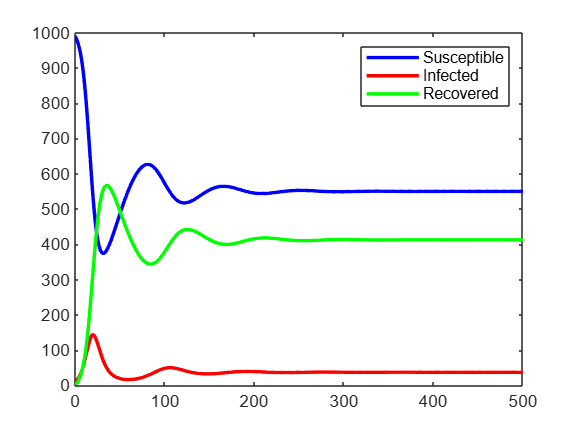

clear all
close all
clc

N=1000;
p=0.5;
c = 1;
L = 0.025;
r = 0.275;
numsteps=500;


I0=10;
S0=N-I0;
R0=0;
F=@(S,I,R) [-p*c*S*I/N+L*R; p*c*S*I/N-r*I; r*I-L*R];

x(:,1)=[S0;I0;R0];
for k=1:numsteps
    curR=x(1,k);
    curI=x(2,k);
    curS=x(3,k);
    x(:,k+1)=x(:,k)+F(curR, curI, curS);
    if curI<1
        curR=curR+curI;
        curI=0;
    end
    if curS<=1
        curI=curI+curS;
        curS=0;
    end
end

plot(0:numsteps,x(1,:),'b','MarkerSize',10,'LineWidth',2)
hold on
plot(0:numsteps,x(2,:),'r','MarkerSize',10,'LineWidth',2)
plot(0:numsteps,x(3,:),'g','MarkerSize',10,'LineWidth',2)

legend('Susceptible', 'Infected', 'Recovered')